# Adversarial capacity simulation

## Parameters

clear all
% Define parameters
% Define parameters
bitsPerSym = 6;
modOrder = 2^bitsPerSym;

% LDPC parameters (5G NR)
coderate = 1/3; % Example: 1/3 rate code
maxNumIter = 50; % Maximum number of decoding iterations
BG =1;
% BG = 2; % Base Graph (BG1 or BG2 depending on the scenario)

% Define input length K and encoded length N for 5G NR
K = 8448; % Length of information bits 
% K = 3840;
N = K / coderate; % Length of codeword (encoded bits)

% Interleaver parameters
interleaverSize = N; % Size of the interleaver (same as codeword length)

% SNR range
% SNRdB = 4:1:20; % SNR values in dB  % DEBUG
SNRdB = (0:0.1:20)';
numSNR = length(SNRdB);

% Methods to test.  For each method, we specify the adversarial type
% and whether clipping is used
advType = {'no adv', 'minimax', 'fix flip', 'minimax', 'fix flip'};
llrClip = [false, true, true, false, false]; 
numMeth = length(advType);


## Calibrate the threshold for the flip probability

We first need to find the mapping of the LLR threshold for the flip probability.  This mapping is different at different SNRs.

nsym = 1e4;
numBits = nsym * bitsPerSym;
llrThreshTest = linspace(0,10,100)';
nthresh = length(llrThreshTest);

% Generate random bits
bits = randi([0 1], numBits, 1);

% QAM modulate
s = qammod(bits, modOrder, 'InputType', 'bit', 'UnitAveragePower', true);

flipProbTest = zeros(nthresh, numSNR);
capFlip = zeros(nthresh, numSNR);
capNoFlip = zeros(numSNR, 1);

for isnr = 1:numSNR
    % Add noise
    snr = SNRdB(isnr);
    noiseVar = db2pow(-snr);
    w = (randn(nsym,1) + 1i*randn(nsym,1))/sqrt(2);
    r = s + db2mag(-snr)*w;

    % Get the LLRs
    z0 = qamdemod(r, modOrder, 'OutputType', 'approxllr', ...
        'UnitAveragePower', true, 'NoiseVariance', noiseVar);

    % Find the accuracy.  Note the negative sign since MATLAB
    % uses the LLR for bit=0 not bit=1.
    z0b = -z0.*(2*bits-1);
    bce = mean(log2(1 + exp(-z0b)));
    capNoFlip(isnr) = 1 - bce;
    
    % Find the flip probability
    for it = 1:nthresh

        % Compute flip prob
        t = llrThreshTest(it);
        p = max(0, (1 - exp(t - z0b)) ./ (1 + exp(t)));
        flipProbTest(it,isnr) = mean(p);
    
        % Flip bits
        u = (rand(numBits,1) < p);
        z0bFlip = -z0b.*(2*u-1);
        
        % Compute capacity 
        bceFlip = mean(log2(1 + exp(-z0bFlip)));
        capFlip(it, isnr) = max(0, 1 - bceFlip);
    end

end

We plot the capacity as a function of the flip probability

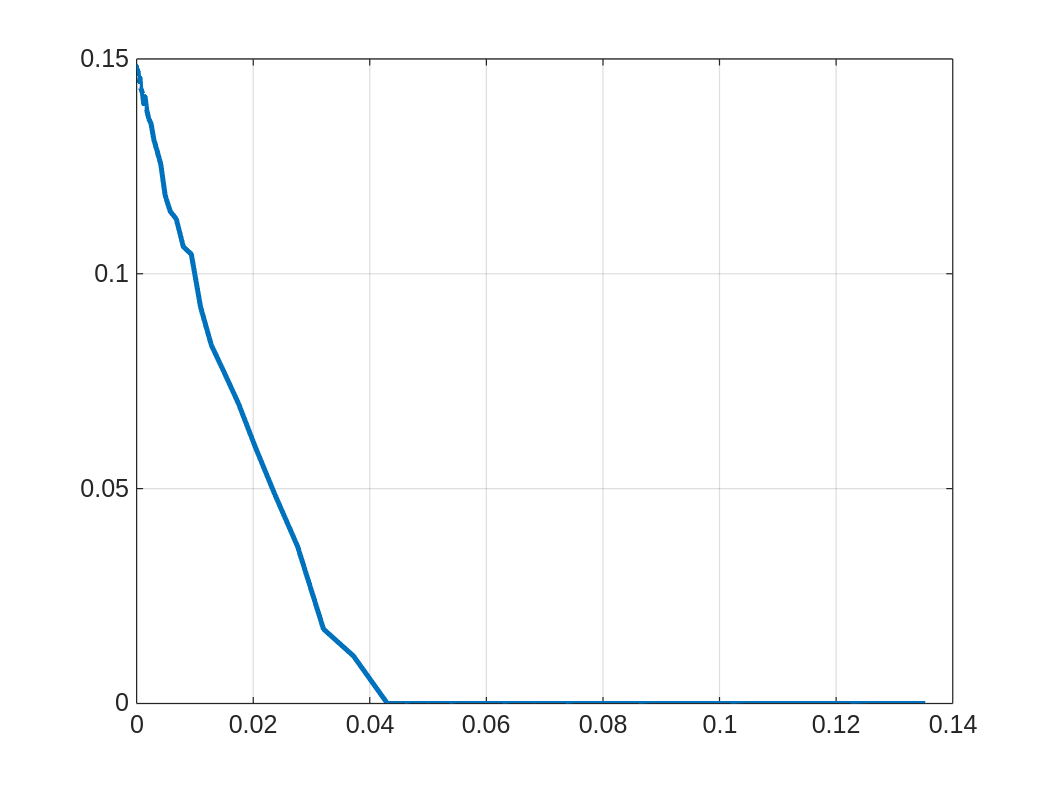

isnr = 10;
plot(flipProbTest(:,isnr), capFlip(:,isnr), 'LineWidth', 2);
grid on;

We plot the t as a function of the flip probability

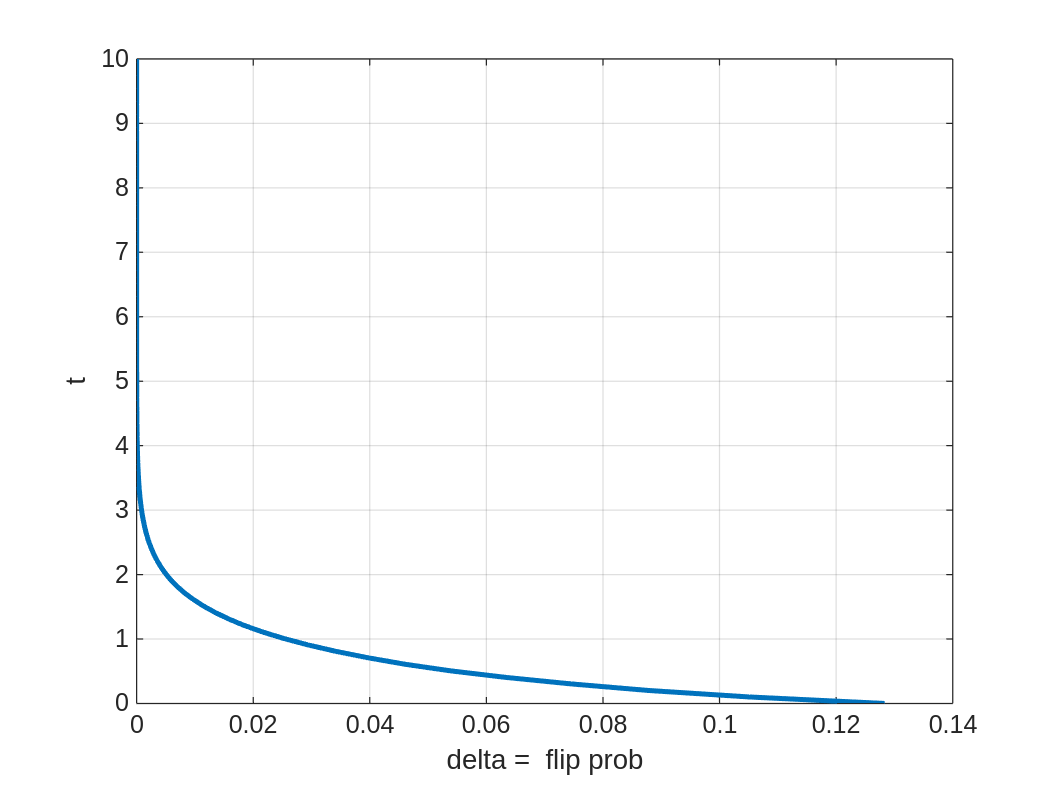

isnr = 5;
plot(flipProbTest(:,isnr), llrThreshTest, 'LineWidth', 2);
xlabel('delta =  flip prob')
ylabel('t')
grid on;

## Simulate the different methods

First we creates strings for each method.  This will be useful for plotting.

methStr = cell(numMeth,1);
for imeth = 1:numMeth
    if llrClip(imeth)
        clipStr = "clip";
    else
        clipStr = "no clip";
    end
    methStr{imeth} = sprintf('%s+%s', advType{imeth}, clipStr);

    fprintf(1, 'Method %d:  %s\n', imeth, methStr{imeth});
end

Method 1:  no adv+no clip
Method 2:  minimax+clip
Method 3:  fix flip+clip
Method 4:  minimax+no clip
Method 5:  fix flip+no clip


tic

numTrials = 10000;

% Flip probability to test
flipProb = 0.01;

BER = zeros(numTrials, numSNR, numMeth);
BLER = zeros(numSNR, numMeth);
flipped = zeros(numTrials, numSNR, numMeth);
llrThresh = zeros(numSNR,1);

BERavg = zeros(numSNR, numMeth);
BLERavg = zeros(numSNR, numMeth);
flipavg = zeros(numSNR, numMeth);
methDone = zeros(numMeth,1);


% Simulation loop over SNR values
for isnr = 1:numSNR

    snr = SNRdB(isnr);

    % Find the LLR threshold via interpolation.
    % Note that the interpolation function requires x to be increasing
    x = flipud(flipProbTest(:,isnr));

    for i = 1:nthresh-1
        if x(i+1) < x(i)
            x(i+1) = x(i);
        end
    end
    
    y = flipud(llrThreshTest);

    [x, uniqueIdx] = unique(x, 'stable');
    y = y(uniqueIdx); % Adjust y to match unique x
    
    t = interp1(x, y, flipProb);
    llrThresh(isnr) = t;

    % Set the threshold for the fixed method
    tfix = 5*t;

    nerr=zeros(numMeth,numTrials);
    nerr_total =  zeros(1,numMeth);
    % Loop for multiple trials
    for it = 1:numTrials
        % Generate random bits (information bits)
        bits = randi([0 1], K, 1);
        encodedDataBits = nrLDPCEncode(bits, BG);  % 5G NR LDPC Encoding

        % Interleaving
        interleavedBits = randintrlv(encodedDataBits, it); % Use trial as seed for reproducibility

        % QAM Modulation (QPSK)
        s = qammod(interleavedBits, modOrder, 'InputType', 'bit', 'UnitAveragePower', true);
        Es = 1; % Energy per symbol

        % Add AWGN noise
        nsym = length(s);
        noise = (randn(nsym,1) + 1i*randn(nsym,1)) / sqrt(2);
        r = s + db2mag(-SNRdB(isnr)) * noise; % Received signal with noise
        
        % LLR Calculation
        noiseVar = db2pow(-SNRdB(isnr));
        z0 = qamdemod(r, modOrder, 'OutputType', 'approxllr', 'UnitAveragePower', true, 'NoiseVariance', noiseVar);
        
        % Compute reliability
        z0b = -z0.*(2*interleavedBits-1);
        numBits = length(z0b);

        % Loop over decoding methods
        for imeth = 1:numMeth

            % Skip over method if already complete
            if methDone(imeth)
                continue
            end

            if strcmp(advType{imeth}, 'no adv')
                z1 = z0;
            elseif strcmp(advType{imeth}, 'minimax')
                p = max(0, (1 - exp(t - z0b)) ./ (1 + exp(t)));
                u = (rand(numBits,1) < p);
                z1 = -z0.*(2*u-1);
            elseif strcmp(advType{imeth}, 'fix flip')
                [zsort, I] = sort(z0b, 'descend');
                nflip = round(numBits*flipProb);
                z1 = z0;
                b = interleavedBits(I(1:nflip));
                z1(I(1:nflip)) = tfix*(2*b-1);
            else
                error('Unknown adversary type')
            end

            % De-interleave
            z1Deint = randdeintrlv(z1, it);

            % Clip the LLR, if required
            if llrClip(imeth)
                z2 = max(-t, z1Deint);
                z2 = min(t, z2);
            else
                z2 = z1Deint;
            end



            % Run the decoder
            decodedBits = nrLDPCDecode(z2, BG, maxNumIter, 'DecisionType', 'hard');

            if any(decodedBits ~= bits)
                nerr(imeth,it)=nerr(imeth,it)+1;
            end


            
            % Measure the BER
            BER(it,isnr,imeth) = mean(decodedBits ~= bits);
     
            flipped(it,isnr,imeth) = mean(z1 ~= z0);

        end
    
    end  

    nerr_total=sum(nerr,2);
    BLER(isnr,:) = nerr_total'./numTrials;
    
    for imeth = 1:numMeth
        % Compute the average values 
        BERavg(isnr,imeth) = mean(BER(:,isnr,imeth));
        BLERavg(isnr,imeth) = BLER(isnr,imeth);
        flipavg(isnr,imeth) = mean(flipped(:,isnr,imeth));
    
    
        % Once we hit a sufficiently small BER we can assume all higher
        % SNRs will make zero erros, so we skip over these
        methDone(imeth) = (BERavg(isnr,imeth) < 1e-8);  

        % fprintf(1, 'SNR=%7.2f meth=%s BER=%12.4e\n', snr, methStr{imeth}, BERavg(isnr,imeth));
        % fprintf(1, 'SNR=%7.2f meth=%s BLER=%12.4e\n', snr, methStr{imeth}, BLERavg(isnr,imeth));
    end

end
toc

save the mat file for the BER and BLER

% Specify the file name
filename = 'BG1_results_1.mat';

% Save the BERavg and BLERavg variables to the file
save(filename, 'BERavg', 'BLERavg','SNRdB','methStr');

% Display a message to confirm
disp(['Results saved to ', filename]);



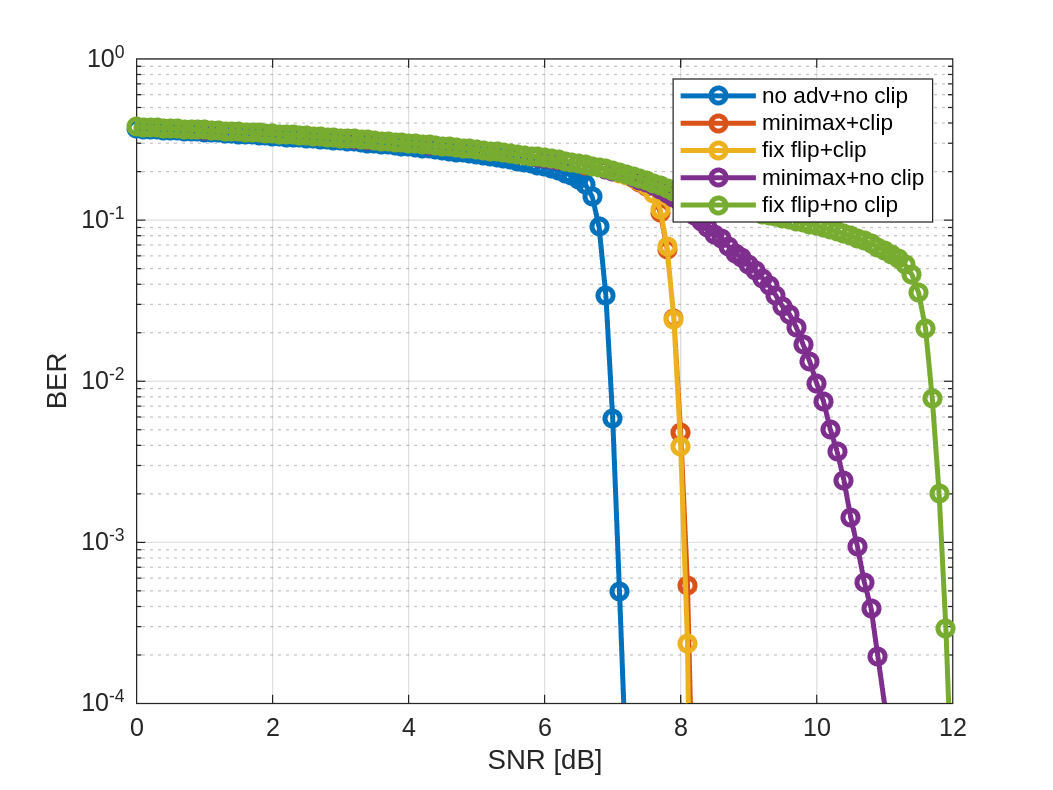



semilogy(SNRdB, BERavg, 'o-', 'linewidth', 2);
legend(methStr);

grid on;
ylim([1e-4,1]);
ylabel('BER');
xlabel('SNR [dB]');

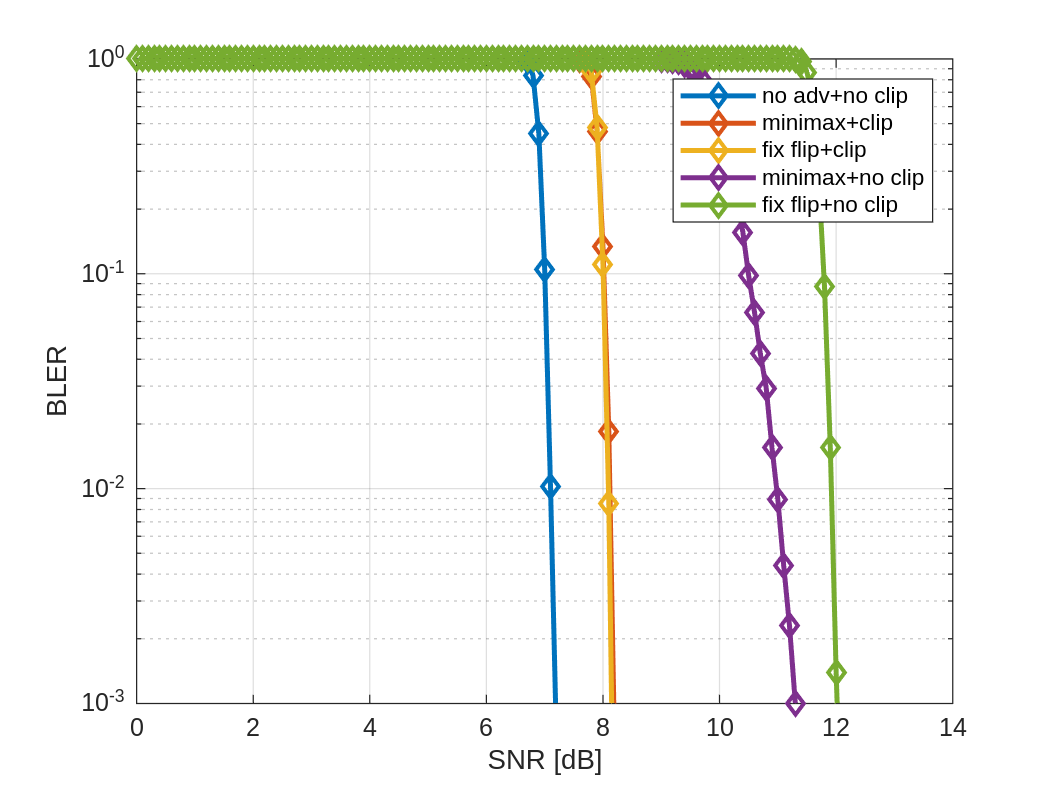


semilogy(SNRdB, BLERavg, 'd-', 'linewidth', 2);
legend(methStr);

grid on;
ylim([1e-3,1]);
ylabel('BLER');
xlabel('SNR [dB]');